***Ejercicio 1:***

***a) ***Dada la funcion f =  @(x) [x.^3+sin(x)]./(exp(x)+15) halle L3 de lagrange usando los nodos x0 = -2.8, x1= -1.1, x2= -2.4, x3 = 5.1

***b) ***El polinomio usando todos los nodos

***c) ***el valor de f(-2.8,-1.1,-2.4)

***d) ***El valor aproximado de f(3.8)

***e) *** El error relativo al aproximar f(3.8) 

***Solucion:***

***a y b***

f =  @(x) (x.^3+sin(x))./(exp(x)+15) %Funcion

f = function_handle with value:
    @(x)(x.^3+sin(x))./(exp(x)+15)


X = [-2.8 -1.1 2.4 5.1] % Vector de Nodos

X =    -2.8000   -1.1000    2.4000    5.1000


Y = f(X) % Imagenes de los nodos

Y =    -1.4798   -0.1449    0.5572    0.7358


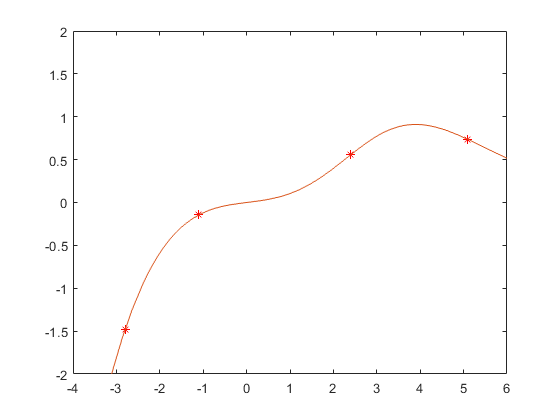

plot(X,Y,"*r") % Nodos graficados
hold on
fplot(f) % Funcion f graficada
axis([-4 6 -2 2])
hold off

Ahora se utiliza la rutina para calcular el polinomio interpolante 

[C, L] = lagran (X, Y) %Rutina que calcula el polinomio iterante de Lagrange

C =     0.0115   -0.0952    0.2746    0.2876


L =    -0.0143    0.0916   -0.0571   -0.1928
    0.0271   -0.1274   -0.2375    0.9290
   -0.0204    0.0244    0.3421    0.3197
    0.0076    0.0113   -0.0475   -0.0559



% L es los L_i del polinomio interpolante, de arriba a abajo sera L_0 -> L_i

% C son los coeficientes del Polinomio, de esta forma, tenemos los rtados
% dados 

Entonces mi polinomio de Lagrange será los coeficientes del C, asi:

**0.0115*x^3-0.0952*x^2+0.02746*X+0.2876**

Y por ejemplo, L2 va a ser:

L_2=-0-0204*x^3+0.0244*x^2+0.3421*x+0.3197

***Grafica del polinomio calculado***

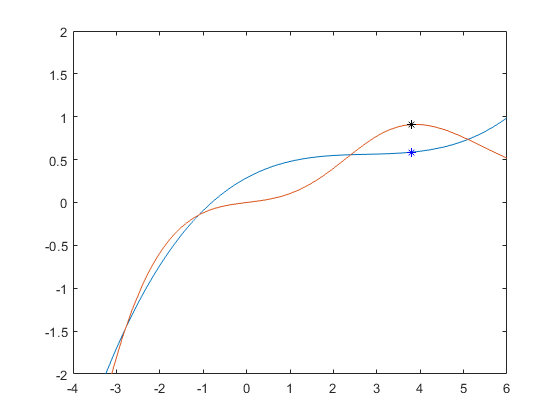

hold off

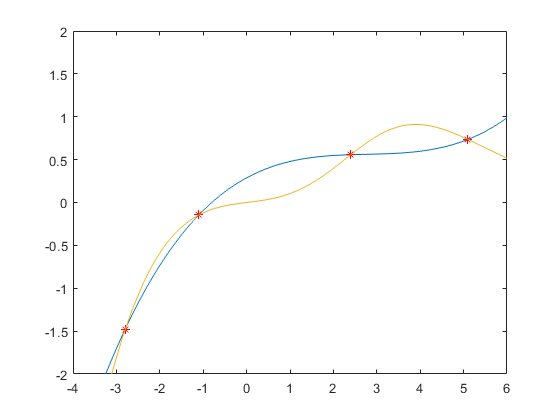

xx = linspace(-4,6,10000); % Grafique esta nube de puntos en el intervalo trabajado
yy = polyval(C,xx); %Evalue la nube de puntos y guardelos en yy
plot(xx,yy) %Grafica de los puntos 
hold on 
plot(X,Y,"*r") % Nodos graficados
fplot(f)
axis([-4 6 -2 2])

***Error relativo***

Para calcular el error relativo en f(punto de interes) se hace asi:

valor abs de la distancia entre real - estimado todo eso sobre el real

(abs(f(3.8)-polyval(C,3.8)))/abs(f(3.8)) %Error del 35% aprox

ans = 0.3543

Grafiquemos los puntos del error

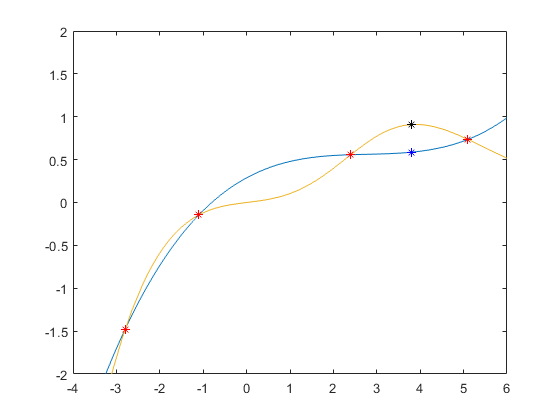

hold on
plot(X,Y,"*r") % Nodos graficados
plot(3.8,f(3.8),"*k") % EL real en nigga
plot(3.8, polyval(C,3.8),"*b") % Estimiado con Lagra en azul como tus ojos bb